# MAIN CODE FILE

- Documentation paragraph that describes what your main code does, in enough detail that a cogent fellow programmer can follow it.

This code controls a wheeled autonomous rover performing a series of three outdoor missions around the Olin Oval. The missions are:

- Waypoint Navigation

- Docking

- Scientific Payload Delivery

This program will prompt the user for a mission number and enter the robot control loop and run the behaviour engine specific to that mission. To find its way around the oval, the rover takes desired location waypoints as inputs. To navigate around potential obstacles in an outdoor environment, the rover has a sensory suite that adds data to a rover-centric occupancy grid. From this grid, a weighted vector (brainwave) is produced that minimizes the potential for collision. Other mission-specific tasks use this concept of brainwave arbitration to determine which steering angle is the best to take.

- Wiring diagram of your robot

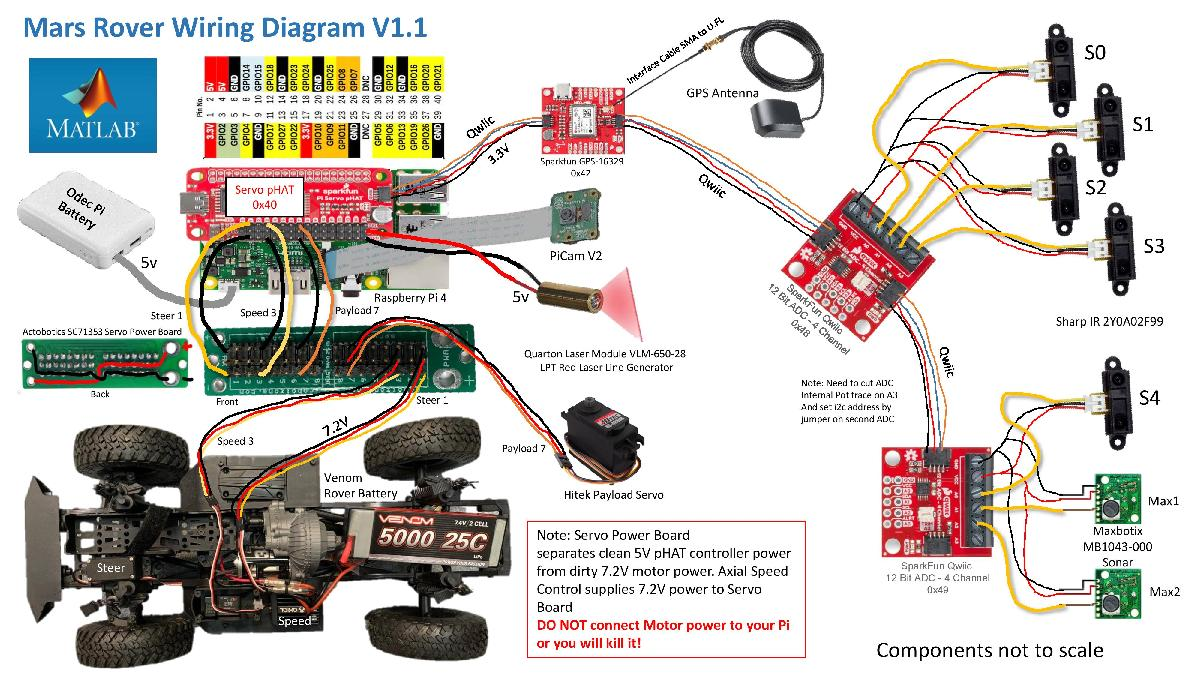

- Clear indication of what external Matlab code parts

The program OlinRoverSetup is used to set up the rover’s Raspberry Pi, sensing and actuation hardware, and create global variables. It's also where mission parameters and data, such as waypoints and the main occupancy grid, are set up.

clc                     % clear command window
clear                   % clear MATLAB workspace
% profile on            % profile used to time each segment of code

## **Set up robot control system** ( code that runs once )

% Set up Raspberry Pi
disp('note: It takes a 10 seconds or so to download code to Raspberry PI '); 

At least one END is missing: the statement may begin here.

[robotPi, blinkLED]= RaspPiSetup()

% Turn on board LED on and off to signal program has started 
Blink(robotPi,blinkLED,10);
disp('Warning! Robot Rover Active! ');

% Set up servos, PiCam, and QWIIC analog input
[roverServos, roverJoy] = ServoSetup(robotPi)
[robotCam] = PiCamSetup(robotPi)
[roverServos, roverJoy] = QWIICInputSetup(robotPi)
% TODO: GPS SETUP

**INITIALIZE ROVER OCCUPANCY GRID**

 %Create an empty map of the same dimensions as the test track map
[mapdimx,mapdimy] = size(bwimage);                           %find size of image
roverOccupancyGrid = binaryOccupancyMap(mapdimx,mapdimy,10,'grid');  %make empty map the same size
g
%create a free floating figure
ovalSharpIRScan = figure('name', 'TugSharpIRScan', 'NumberTitle', 'off', 'Visible', 'on');
figure(ovalSharpIRScan)                            
    show(roverOccupancyGrid);                %show the map in a figure window
    grid on;
    grid minor;
    
% figure for live video feed
liveVideo = figure('name', 'ovalVideoFeed', 'NumberTitle', 'off', 'Visible', 'on');

**CREATE GLOBAL VARIABLES**

sampleTime = 0.5;                                  % Sample time [s]
t = 0:sampleTime:100;                              % Time array
r = rateControl(1/sampleTime);                     % reset control loop  rate
reset(r);                                          % reset loop time to zero

**ASK FOR MISSION NUMBER**

mission_number = input('Enter mission number: ');

**READY TO RUN ROBOT?**

userInput = questdlg('Ready to run Rover?', 'Start Mission');

## Run Robot Control Loop

if (strcmp(userInput,'Yes'))
    comSteer = 50;                       % set steering center
    comSpeed = 50;                       % set drivespeed to zero
    controlFlag = 1;                     % create a loop control
end

switch mission_number
    case 1 % mission 1: driving
       while true
           % SENSE: collect data about surroundings
           [roverOccupancyGrid] =  SharpIRRange(roverOccupancyGrid) % IR Data
           [roverOccupancyGrid] =  SonarRange(roverOccupancyGrid) % Sonar Data
           [roverOccupancyGrid, roverBearing, roverLocation] = GPSGetLocation(roverOccupancyGrid) % GPS
           [roverOcupancyGrid] = PiCamLaser(roverOcupancyGrid) % obstacles with laser 
           %-----------------------------------------------------------------------------
           % THINK: make decisions about where to go
           [waypointSteeringVector] = GoToWayPoint(roverOcupancyGrid,targetWaypoint) % go to waypoint 
           [avoidSteeringVector] = ObstacleAvoid(roverOcupancyGrid) %avoid obstacles
           [wallSteeringVector] = WallFollow(roverOcupancyGrid, direction) %follow walls
           
           % Use Arbiter to combine multiple behaviours together
           [direction, speed] = roverArbiter(waypointSteeringVector, avoidSteeringVector, wallSteeringVector) 
           %-----------------------------------------------------------------------------
           % ACT : drive the rover
           DriveRover(robotPi,roverServos,direction,speed)
           
           % think about how we want to control the pan tilt and what will
           % affect that 
           DrivePanTilt(panAngle, tiltAngle)
           %-----------------------------------------------------------------------------
           
       end
        
    case 2 % mission 2: docking
       while true
           % SENSE: collect data about surroundings
           [roverOccupancyGrid] =  SharpIRRange(roverOccupancyGrid) % IR Data
           [roverOccupancyGrid] =  SonarRange(roverOccupancyGrid) % Sonar Data
           [roverOccupancyGrid, roverBearing, roverLocation] = GPSGetLocation(roverOccupancyGrid) % GPS
           [roverOcupancyGrid] = PiCamLaser(roverOcupancyGrid) % obstacles with laser 
           [roverOcupancyGrid]  =  PiCamAprilTagFind(roverOcupancyGrid,panAngle, tiltAngle) % find dock using april tag
           [roverOccupancyGrid]  =  PiCamDockFind(roverOccupancyGrid, panAngle, tiltAngle) % find dock using picam
           %-----------------------------------------------------------------------------
           % THINK: make decisions about where to go
           [waypointSteeringVector] = GoToWayPoint(roverOcupancyGrid,targetWaypoint) % go to waypoint 
           [avoidSteeringVector] = ObstacleAvoid(roverOcupancyGrid) %avoid obstacles
           [wallSteeringVector] = WallFollow(roverOcupancyGrid, direction) %follow walls
           [dotSteeringVector] = RedDotDockRover(roverOcupancyGrid) % find rover using red dot
           [tagSteeringVector] = AprilTagDockRover(roverOcupancyGrid) % find rover using april tag
           
           
           % Use Arbiter to combine multiple behaviours together
           [direction, speed] = roverArbiter(waypointSteeringVector, avoidSteeringVector, wallSteeringVector, dotSteeringVector, tagSteeringVector) 
           %-----------------------------------------------------------------------------
           % ACT : drive the rover
           DriveRover(robotPi,roverServos,direction,speed)
           
           % think about how we want to control the pan tilt and what will
           % affect that 
           DrivePanTilt(panAngle, tiltAngle)
           %-----------------------------------------------------------------------------
           
       end        
        
    case 3 % mission 3: payload
        while true
           % SENSE: collect data about surroundings
           [roverOccupancyGrid] =  SharpIRRange(roverOccupancyGrid) % IR Data
           [roverOccupancyGrid] =  SonarRange(roverOccupancyGrid) % Sonar Data
           [roverOccupancyGrid, roverBearing, roverLocation] = GPSGetLocation(roverOccupancyGrid) % GPS
           [roverOcupancyGrid] = PiCamLaser(roverOcupancyGrid) % obstacles with laser 
           [roverOcupancyGrid]  =  PiCamAprilTagFind(roverOcupancyGrid,panAngle, tiltAngle) % find dock using april tag
           
           %-----------------------------------------------------------------------------
           % THINK: make decisions about where to go
           [waypointSteeringVector] = GoToWayPoint(roverOcupancyGrid,targetWaypoint) % go to waypoint 
           [avoidSteeringVector] = ObstacleAvoid(roverOcupancyGrid) %avoid obstacles
           [wallSteeringVector] = WallFollow(roverOcupancyGrid, direction) %follow walls           
           [tagSteeringVector] = AprilTagDockRover(roverOcupancyGrid) % find rover using april tag( use the check function inside this function to simplify)       
           
           % Use Arbiter to combine multiple behaviours together
           [direction, speed] = roverArbiter3(waypointSteeringVector, avoidSteeringVector, wallSteeringVector, tagSteeringVector) 
           %-----------------------------------------------------------------------------
           % ACT : drive the rover
           DriveRover(robotPi,roverServos,direction,speed)
           % how will we know we are in the right spot?
           if at_dock
               DeployPayload(payloadNumber)
           end
           % think about how we want to control the pan tilt and what will
           % affect that 
           DrivePanTilt(panAngle, tiltAngle)
           %-----------------------------------------------------------------------------
           
       end  
        
end

## Robot Functions(store the local functions here)

**SENSE FUNCTIONS**

function[roverOccupancyGrid] =  SharpIRRange(roverOccupancyGrid) % fill in other variable
% Mark obstacles based on the positions on the grid
end

function[roverOccupancyGrid] =  SonarRange(roverOccupancyGrid) % fill in other variables
% Mark obstacles based on the positions on the grid
end

function[roverOccupancyGrid, roverBearing, roverLocation] = GPSGetLocation(roverOccupancyGrid) % this will be provided from canvas
% Get rovers current location, and output it
end

function[roverOccupancyGrid]  =  PiCamDockFind(roverOccupancyGrid, panAngle, tiltAngle) 
% Find the location of the red dot, and mark it on the grid
end
 
function[roverOcupancyGrid] = PiCamLaser(roverOcupancyGrid) % laser for obstacle avoidance
% Mark obstacles on the grid
end

function[roverOcupancyGrid]  =  PiCamAprilTagFind(roverOcupancyGrid,panAngle, tiltAngle) %why is there pan and tilt angle
% Find the location of the april tags and mark it on the grid
end

**THINK FUNCTIONS**

function [bumbleBeeSteeringVector] = GoToWayPoint(roverOcupancyGrid,targetWaypoint)
% Create a steering brainwave based on the positions of the waypoints.
end

function [bumbleBeeSteeringVector] = ObstacleAvoid(roverOcupancyGrid)  
% Create a steering brainwave based on the the positions of the obstacles
end

function [bumbleBeeSteeringVector] = WallFollow(roverOcupancyGrid, direction)
% Create a steering brainwave based on the location of the walls around the
% rover
end

function [bumbleBeeSteeringVector] = RedDotDockRover(roverOcupancyGrid)
% Create a steering brainwave based on the coordinates of the red dot above
% the dock
end

function [bumbleBeeSteeringVector] = AprilTagDockRover(roverOcupancyGrid)
% Create a steering brainwave based on the information found from the
% apriltag onthe dock
end

function [tag] = CheckAprilTag(roverOccupancyGrid)
% Check to see if the April Tag is ours or not and output yes or no
end

function [direction, speed] = roverArbiter1(behavior1, behavior2, behavior3)
% From all the brainwaves generated from the different behaivours, output a
% final direction and speed for the motors for mission 1.
end

function [direction, speed] = roverArbiter2(behavior1, behavior2, behavior3, behavior4, behavior5)
% From all the brainwaves generated from the different behaivours, output a
% final direction and speed for the motors for mission 2.
end

function [direction, speed] = roverArbiter3(behavior1, behavior2, behavior3,behavior4)
% From all the brainwaves generated from the different behaivours, output a
% final direction and speed for the motors for mission 3.
end

**ACT FUNCTIONS**

function [] = DrivePanTilt(panAngle, tiltAngle)
end

function [] = DeployPayload(payloadNumber)
end

function [] = DriveRover(robotPi,roverServos,direction,speed)
end